# EJEMPLO     

Aproximar la solución del problema de valor inicial  $\frac{dy}{dt}=2y-1$ con condición inicial $$y(0)=1$$ con $\Delta t=0.1$ sobre el intevalo $0\leq t \leq 1$.

Identificamos que la ecuación $f(t,y)=f(y)=2y-1$ y discretizamos la ecuación diferencial de la siguiente forma.

## 
$$y(t_{n+1})=y(t_n)+\left[2\,y(t_n)-1\right]\Delta t$$


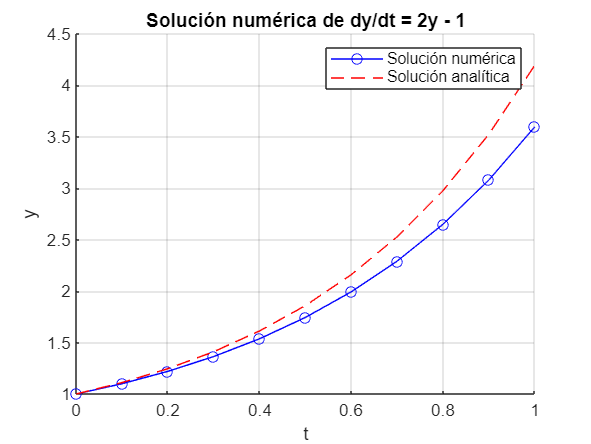

clc, clear, close all
%% Solución numérica de la ecuación diferencial dy/dt = 2y - 1
% Intervalo de tiempo
dt = 0.1; % parámetro que refina el modelo cuando dt->0
t = 0:dt:1; % valores del tiempo espaciados con el intervalo dt

% Condición inicial
y0 = 1; % Puedes cambiar esta condición inicial según sea necesario
y = zeros(size(t))'; % inicialización del vector solución en ceros
y(1) = y0; %condición inicial para el tiempo t=0,

% Método de Euler para resolver la ecuación diferencial
for i = 2:length(t)
    y(i) = y(i-1) + dt * (2*y(i-1) - 1);
end

% Graficar la solución numérica
figure;
hold on;
plot(t, y, 'b-o');
title('Solución numérica de dy/dt = 2y - 1');
xlabel('t');
ylabel('y');
grid on;

%% Solución analítica de la ecuación diferencial
% y(t) = C*exp(2t) + 0.5
% donde C es una constante determinada por la condición inicial
C = (y0 - 0.5);
y_analitica = (C*exp(2*t) + 0.5)';

% Graficar la solución analítica

plot(t, y_analitica, 'r--');
legend('Solución numérica', 'Solución analítica');
hold off;

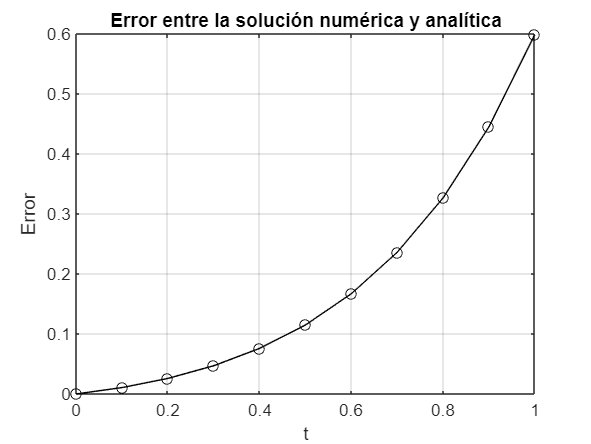


% Calcular el error entre la solución numérica y la solución analítica
error = abs(y - y_analitica);

figure;
plot(t, error, 'k-o');
title('Error entre la solución numérica y analítica');
xlabel('t');
ylabel('Error');
grid on;

### Ahora calcuemos el intervalo $\Delta t$ tal que el $error<0.1$

Para ello tenemos que crear un vector con todas las opciones $0.1\leq\Delta t\leq0.0001$ en el intervalo $0\leq t \leq 1$.

Usamos la función *linspace.*

% clc, clear, close all

% function error=(f(t,y),función analitica)
dt=linspace(0.1,0.0001,1000); %intervalo de calculo 


%Calculo del error< 0.1
for j = 1 : length(dt)

t=0:dt(j):1; %intervalo total del tiempo en el modelo
%Condición inicial
y0=1;
y=zeros(size(t));
y(1)=y0;

%Metodo de Euler
for i = 2 : length(t)
    y(i) = y(i-1)+(y(i-1))*dt(j); %iteración de Euler
end

%Solución analítica
y_analitica=exp(t); %sol. analítica

% Error
error= abs(y - y_analitica);

if max(error)<0.1
    fprintf('encontramos el intervalo dt=%f \ndonde el error=%f es menor a 1\n',dt(j),max(error))
    break
end
end

encontramos el intervalo dt=0.092600 
donde el error=0.099948 es menor a 1


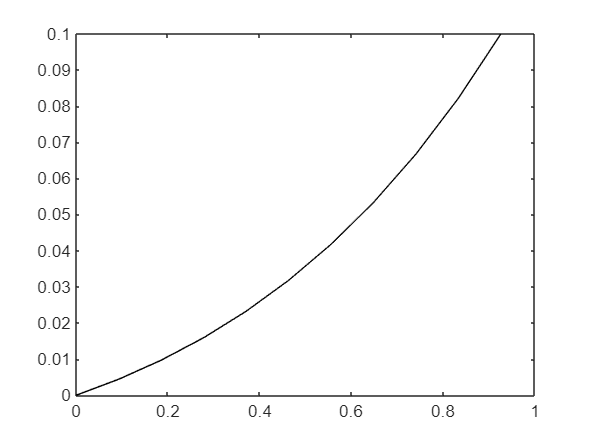


%Grafica del error
figure
plot(t,error,'k-')

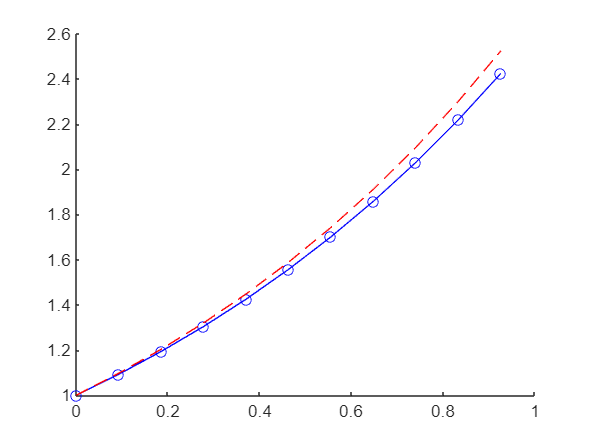


% Grafica la solución con Euler
figure
hold on;
plot(t,y,'b-o');
plot(t,y_analitica,'r--')
hold off